# Generation Location

## location

GSL

GSL = 10×4 table
         GenerationSites           Village      Longitude    Latitiude
    _________________________    ___________    _________    _________

    "Popua Power Station"        "Ánana"         -175.18      -21.159 
    "Maama Mai Solar Farm"       "Ánana"         -175.18      -21.158 
    "Mata ó e Laá Solar Farm"    "Vaini"         -175.19      -21.191 
    "Singyes Solar Farm"         "Tofoa"         -175.23       -21.16 
    "Sunergise 1"                "Fualu"         -175.27      -21.145 
    "Sunergise 2"                "Masilamea"     -175.33      -21.136 
    "Sunergise 3"                "Kolovai"       -175.35      -21.101 
    "I o Manumataongo"           "Niutoua"       -175.04      -21.153 
    "BESS 1"                     "Tofoa"         -175.23      -21.162 
    "Bess 2"                     "Ánana"         -175.18      -21

## Mapping

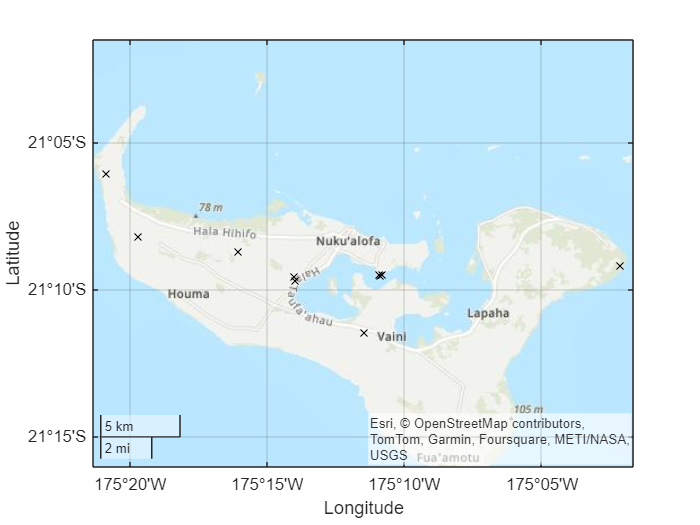

figure;
geoscatter(GSL.Latitiude, GSL.Longitude, "xk")
geobasemap topographic
saveas(gcf, 'geoscatter_map.png');

fname = 'geoscatter_map.png'; % Locates sample image. See helper function at end of file
% Read in the file
stop = imread(fname);
% View the size of the image
numDimension = size(stop)

numDimension =    656   875     3


imshow(stop)

darkImage = imadjust(stop, [0.7 0.4 0.4; 1 1 1]);
imshowpair(stop, darkImage, "montage")

# **Import** Data

TPL = importfile("All_Data.xlsx")

TPL = 222×19 table
       MONTH       GENERATED      SENT_OUT       BILLED      PARASITIC        LINE         TOTAL       PARASITIC_PERCENTAGE    LINE_PERCENTAGE    TOTAL_PERCENTAGE    AVERAGE_PARASITIC_PAST_12_MONTHS    AVERAGE_LINE_PAST_12_MONTHS    AVERAGE_TOTAL_PAST_12_MONTHS    TARGET_PERCENTAGE     FUEL_USE     DIESEL_GEN    RE_GEN    FUEL_EFFICIENCY_DIESEL    FUEL_EFFICIENCY_WITH_RE
    ___________    __________    __________    __________    __________    __________    __________    ____________________    _____________

TPL1 =TPL;
TPL1 = removevars(TPL1,[ "PARASITIC_PERCENTAGE", "LINE_PERCENTAGE", "TOTAL_PERCENTAGE", "AVERAGE_PARASITIC_PAST_12_MONTHS", "AVERAGE_LINE_PAST_12_MONTHS", "AVERAGE_TOTAL_PAST_12_MONTHS","FUEL_USE", "DIESEL_GEN","FUEL_EFFICIENCY_DIESEL", "FUEL_EFFICIENCY_WITH_RE"]);
TPL1

TPL1 = 222×9 table
       MONTH       GENERATED      SENT_OUT       BILLED      PARASITIC        LINE         TOTAL       TARGET_PERCENTAGE    RE_GEN
    ___________    __________    __________    __________    __________    __________    __________    _________________    ______

    01-Jul-2006    4.3997e+06    4.3213e+06    3.5367e+06         78445    7.8458e+05    8.6302e+05          0.13             0   
    01-Aug-2006    4.5034e+06    4.4222e+06    4.0388e+06         81284    3.8336e+05    4.6464e+05          0.13             0   
    01-Sep-2006    4.3861e+06    4.2912e+06    3.3732e+06         94877    9.1802e+05    1.0129e+06          0.13             0   
    01-Oct-2006    


scatter(TPL1.MONTH, TPL1.BILLED, 'filled')
legend("Billed")

%xlabel("Parasitic & Line Losses")
%ylabel("Month")
%ylim([-2402556 1877616])


# Exploring Data

## Histogram Of the Data "Generation"

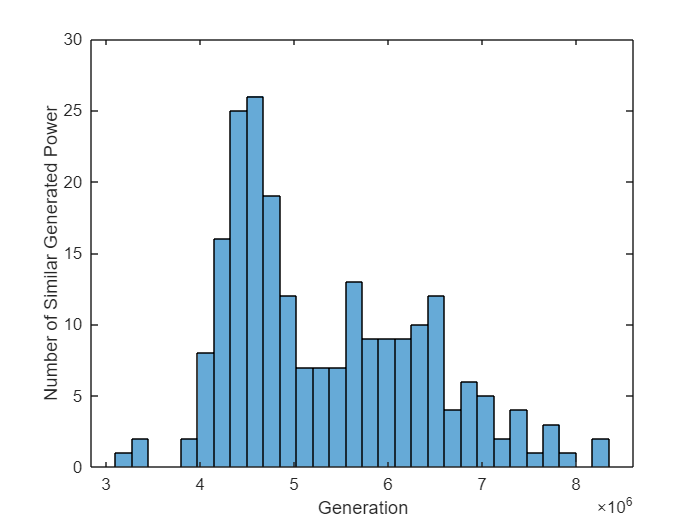

histogram(TPL1.GENERATED, 30)
xlabel("Generation")
ylabel("Number of Similar Generated Power")

## Difference between the Sent Gen vs Billed Gen (Parasitic Losses)

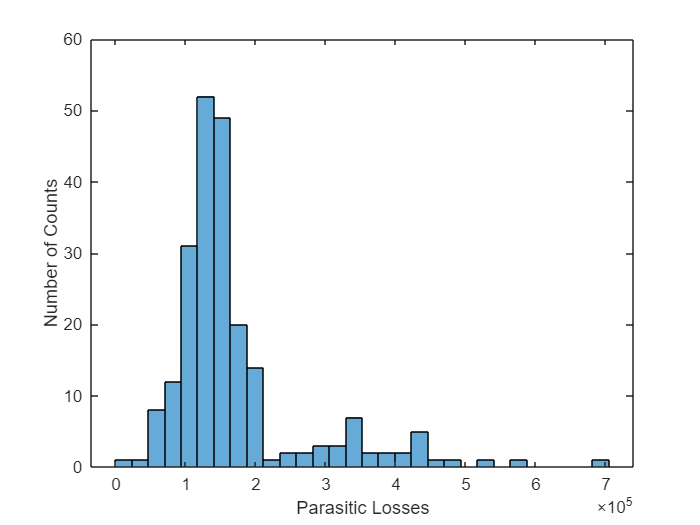

histogram(TPL1.PARASITIC, 30)
xlabel("Parasitic Losses")
ylabel("Number of Counts")

## Difference between the Gen vs Sent Out Gen (Line Losses)

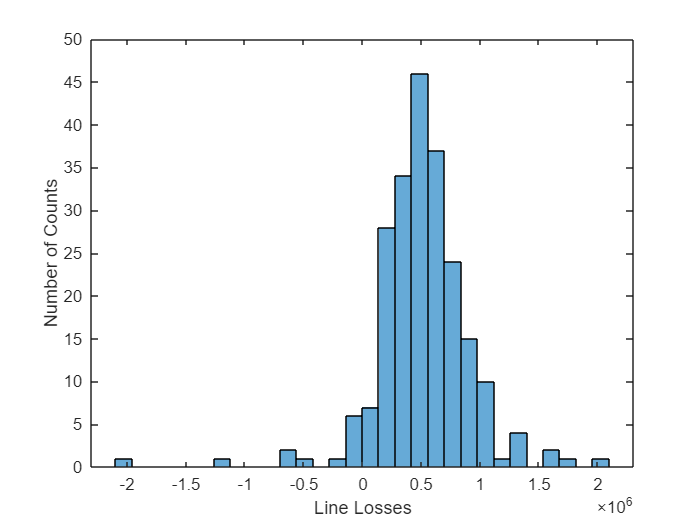

histogram(TPL1.LINE, 30)
xlabel("Line Losses")
ylabel("Number of Counts")

## Correlation (Parasitc and Line Losses)

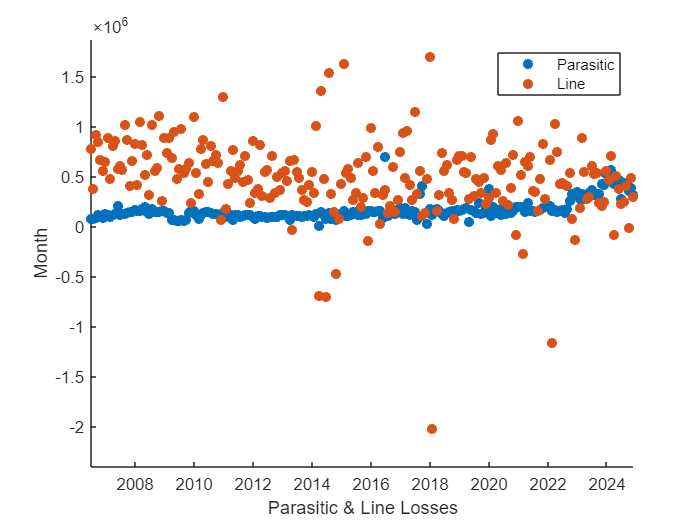

scatter(TPL1.MONTH, [TPL1.PARASITIC, TPL1.LINE], 'filled')
legend("Parasitic","Line")
xlabel("Parasitic & Line Losses")
ylabel("Month")
ylim([-2402556 1877616])


LossesCorrealtion = corr(TPL.PARASITIC, TPL.LINE, "rows","complete")

LossesCorrealtion = -0.0488

## Scatter Plot of Gen, Sent and Billed

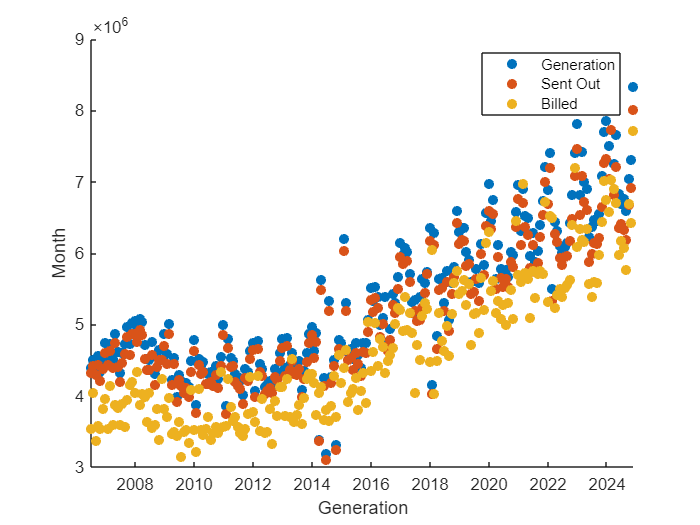


scatter(TPL1.MONTH, [TPL1.GENERATED, TPL1.SENT_OUT, TPL1.BILLED], '')
legend("Generation","Sent Out", "Billed")
xlabel('Generation')
ylabel('Month')

LossesCorrealtion1 = corr([TPL1.GENERATED, TPL1.SENT_OUT, TPL1.BILLED], "rows","complete")

LossesCorrealtion1 =     1.0000    0.9974    0.9187
    0.9974    1.0000    0.9169
    0.9187    0.9169    1.0000


## Histogram ("." bandwidths)

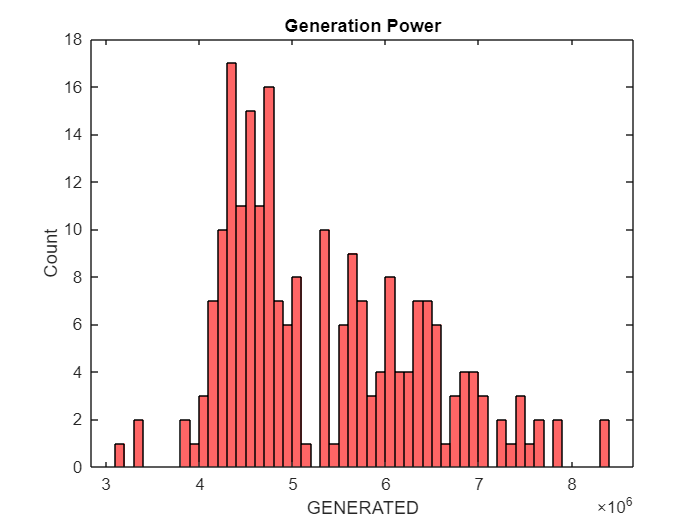

histogram(TPL1.GENERATED, "BinWidth", 100000, "FaceColor", "r")
title("Generation Power")
ylabel("Count")
xlabel("GENERATED")

## Exploring the Data (Highest Generation) 

% Ensure 'TPL' is a table
if ~istable(TPL1)
    error('The variable "TPL" must be a table.');
end

% Convert categorical Month to string first, then to datetime
TPL1.MonthYear = datetime(string(TPL1.MONTH), 'InputFormat', "dd-MMM-uuuu"); 



% Ensure 'GeneratedPower' column exists
if ~any(strcmp("GENERATED", TPL1.Properties.VariableNames))
    error('GeneratedPower column is missing from the dataset.');
end

% Group by month and find the maximum generated power
summaryTable = groupsummary(TPL1,"MONTH", "max", "GENERATED");

% Find the month with the highest generated power
[~, idx] = max(summaryTable.max_GENERATED);
highestMonth = summaryTable.MONTH(idx);

% Display the result
disp(['The month with the highest generated power is: ', char(highestMonth)]);

The month with the highest generated power is: 01-Dec-2024


## Every Year Explorations (Yearly max Month, Min Month, Percentage/Ratio increment)

% Ensure 'TPL1' is a table
if ~istable(TPL1)
    error('The variable "TPL1" must be a table.');
end

% Convert categorical Month to string first, then to datetime
TPL1.MonthYear = datetime(string(TPL1.MONTH), 'InputFormat', "dd-MMM-uuuu"); 

% Ensure 'GENERATED' column exists
if ~any(strcmp("BILLED", TPL1.Properties.VariableNames))
    error('BILLED column is missing from the dataset.');
end

% Extract financial year (July–June)
TPL1.FinancialYear = TPL1.MonthYear;
TPL1.FinancialYear(TPL1.MonthYear.Month >= 7) = TPL1.FinancialYear(TPL1.MonthYear.Month >= 7) + calyears(1);
TPL1.FinancialYear = year(TPL1.FinancialYear);

% Group by financial year and month, summing up the generated power
summaryTable = groupsummary(TPL1, ["FinancialYear", "MonthYear"], "sum", "BILLED");

% Find max and min generated power per financial year
maxTable = groupsummary(summaryTable, "FinancialYear", "max", "sum_BILLED");
minTable = groupsummary(summaryTable, "FinancialYear", "min", "sum_BILLED");

% Merge the max and min values with the corresponding months
maxIdx = arrayfun(@(y) find(summaryTable.FinancialYear == y & ...
    summaryTable.sum_BILLED == maxTable.max_sum_BILLED(maxTable.FinancialYear == y), 1), maxTable.FinancialYear);
minIdx = arrayfun(@(y) find(summaryTable.FinancialYear == y & ...
    summaryTable.sum_BILLED == minTable.min_sum_BILLED(minTable.FinancialYear == y), 1), minTable.FinancialYear);

% Assign the corresponding months
maxMonths = summaryTable.MonthYear(maxIdx);
minMonths = summaryTable.MonthYear(minIdx);

% Compute month-to-month percentage change within each financial year
summaryTable.PercentageChange = [NaN; diff(summaryTable.sum_BILLED) ./ summaryTable.sum_BILLED(1:end-1) * 100];

% Store results in a final table
PowerTable = table(maxTable.FinancialYear, maxMonths, minMonths, ...
                   maxTable.max_sum_BILLED, minTable.min_sum_BILLED);
PowerTable.Properties.VariableNames = {'FinancialYear', 'MaxMonth', 'MinMonth', 'MaxBILLED', 'MinBILLED'};

% Display results
disp("Yearly Maximum and Minimum BILLED Power:");

Yearly Maximum and Minimum BILLED Power:


disp(PowerTable);

    FinancialYear     MaxMonth       MinMonth      MaxBILLED     MinBILLED 
    _____________    ___________    ___________    __________    __________

        2007         01-Mar-2007    01-Sep-2006     4.144e+06    3.3732e+06
        2008         01-Feb-2008    01-Sep-2007    4.3422e+06    3.5704e+06
        2009         01-Dec-2008    01-Nov-2008    4.2414e+06    3.3885e+06
        2010         01-Mar-2010    01-Aug-2009    4.1025e+06    3.1526e+06
        2011         01-Dec-2010    01-Aug-2010    4.3428e+06    3.3893e+06
        2012         01-Mar-2012    01-Sep-2011    4.2851e+06    3.4465e+06
        2013         01-May-2013    01-Sep-2012     4.515e+06    3.3331e+06
        2014         01-Dec-2013    01-Sep-2013     4.317e+06    3.6088e+06
        2015         01-Mar-2015    01-Aug-2014    4.6502e+06    3.64

# Applying PCA

%TPL = removevars(TPL,[ "MONTH","PARASITIC_PERCENTAGE", "LINE_PERCENTAGE", "TOTAL_PERCENTAGE", "AVERAGE_PARASITIC_PAST_12_MONTHS", "AVERAGE_LINE_PAST_12_MONTHS", "AVERAGE_TOTAL_PAST_12_MONTHS","FUEL_USE", "DIESEL_GEN","FUEL_EFFICIENCY_DIESEL", "FUEL_EFFICIENCY_WITH_RE"]);
%TPL1 = TPL;
TPL1 = removevars(TPL,["MONTH"]);
tbl = TPL1

tbl = 222×8 table
    GENERATED      SENT_OUT       BILLED      PARASITIC        LINE         TOTAL       TARGET_PERCENTAGE    RE_GEN
    __________    __________    __________    __________    __________    __________    _________________    ______

    4.3997e+06    4.3213e+06    3.5367e+06         78445    7.8458e+05    8.6302e+05          0.13             0   
    4.5034e+06    4.4222e+06    4.0388e+06         81284    3.8336e+05    4.6464e+05          0.13             0   
    4.3861e+06    4.2912e+06    3.3732e+06         94877    9.1802e+05    1.0129e+06          0.13             0   
    4.5593e+06    4.4386e+06    3.5816e+06    1.2075e+05    8.5697e+05    9.7772e+05          0.13             0   
    4.3327e+0

 %Convert to array
X = tbl{:,:};

mu = mean(X); % Row vector of column (feature) means
r = range(X); % Row vector of column ranges
X = (X-mu)./r; % Scaled feature matrix


[P,S,V] = pca(X)

P =    -0.3362    0.3155    0.1291    0.3290   -0.0200   -0.1996    0.7713   -0.1654
   -0.3271    0.3066    0.0417    0.4054    0.0549    0.7541   -0.2465    0.0222
   -0.3725   -0.1918    0.2431    0.5162   -0.0532   -0.5230   -0.4545    0.1259
   -0.1780    0.1698    0.6638   -0.4310   -0.5385    0.0703   -0.0427    0.1275
    0.0224    0.5806   -0.2204   -0.0883    0.1250   -0.2130   -0.0471    0.7367
   -0.0076    0.6028   -0.1072   -0.1593    0.0337   -0.2602   -0.3656   -0.6303
    0.6881    0.1801    0.5642    0.3251    0.2647   -0.0000    0.0000    0.0000
   -0.3681   -0.0889    0.3215   -0.3692    0.7854    0.0000    0.0000    0.0000


S =     0.5704    0.0634   -0.0586   -0.0120    0.0176   -0.0000   -0.0000    0.0000
    0.5137   -0.0592    0.0063    0.0821   -0.0052   -0.0000    0.0000    0.0000
    0.5829    0.1123   -0.0632   -0.0527    0.0117    0.0000    0.0000   -0.0000
    0.5378    0.1159   -0.0175   -0.0193   -0.0120    0.0000    0.0000    0.0000
    0.5711    0.0341   -0.0178   -0.0408   -0.0157   -0.0000    0.0000   -0.0000
    0.5340    0.0027   -0.0088    0.0316   -0.0062   -0.0000   -0.0000    0.0000
    0.4810    0.0656    0.0318    0.0569   -0.0287    0.0000   -0.0000    0.0000
    0.5406    0.1270   -0.0205   -0.0265   -0.0116   -0.0000    0.0000   -0.0000
    0.4695    0.0034    0.0358    0.1026   -0.0213   -0.0000   -0.0000    0.0000
    0.5432    0.0955   -0.0176   -0.0194   -0.0118   -0.0000    0.0000    0.0000


V =     0.3272
    0.0265
    0.0136
    0.0103
    0.0061
    0.0000
    0.0000
    0.0000


[coeff, score, latent, tsquared, explained, mu] = pca(X)

coeff =    -0.3362    0.3155    0.1291    0.3290   -0.0200   -0.1996    0.7713   -0.1654
   -0.3271    0.3066    0.0417    0.4054    0.0549    0.7541   -0.2465    0.0222
   -0.3725   -0.1918    0.2431    0.5162   -0.0532   -0.5230   -0.4545    0.1259
   -0.1780    0.1698    0.6638   -0.4310   -0.5385    0.0703   -0.0427    0.1275
    0.0224    0.5806   -0.2204   -0.0883    0.1250   -0.2130   -0.0471    0.7367
   -0.0076    0.6028   -0.1072   -0.1593    0.0337   -0.2602   -0.3656   -0.6303
    0.6881    0.1801    0.5642    0.3251    0.2647   -0.0000    0.0000    0.0000
   -0.3681   -0.0889    0.3215   -0.3692    0.7854    0.0000    0.0000    0.0000


score =     0.5704    0.0634   -0.0586   -0.0120    0.0176   -0.0000   -0.0000    0.0000
    0.5137   -0.0592    0.0063    0.0821   -0.0052   -0.0000    0.0000    0.0000
    0.5829    0.1123   -0.0632   -0.0527    0.0117    0.0000    0.0000   -0.0000
    0.5378    0.1159   -0.0175   -0.0193   -0.0120    0.0000    0.0000    0.0000
    0.5711    0.0341   -0.0178   -0.0408   -0.0157   -0.0000    0.0000   -0.0000
    0.5340    0.0027   -0.0088    0.0316   -0.0062   -0.0000   -0.0000    0.0000
    0.4810    0.0656    0.0318    0.0569   -0.0287    0.0000   -0.0000    0.0000
    0.5406    0.1270   -0.0205   -0.0265   -0.0116   -0.0000    0.0000   -0.0000
    0.4695    0.0034    0.0358    0.1026   -0.0213   -0.0000   -0.0000    0.0000
    0.5432    0.0955   -0.0176   -0.0194   -0.0118   -0.0000    0.0000    0.0000


latent =     0.3272
    0.0265
    0.0136
    0.0103
    0.0061
    0.0000
    0.0000
    0.0000


tsquared =     1.4631
    1.6021
    2.1007
    1.4739
    1.2671
    0.9814
    1.3958
    1.6239
    1.8688
    1.3287


explained =    85.2919
    6.9051
    3.5497
    2.6753
    1.5781
    0.0000
    0.0000
    0.0000


mu = 1.0e-14 *

   -0.0028   -0.0341   -0.0067   -0.0007   -0.0002   -0.0023    0.1892   -0.0004


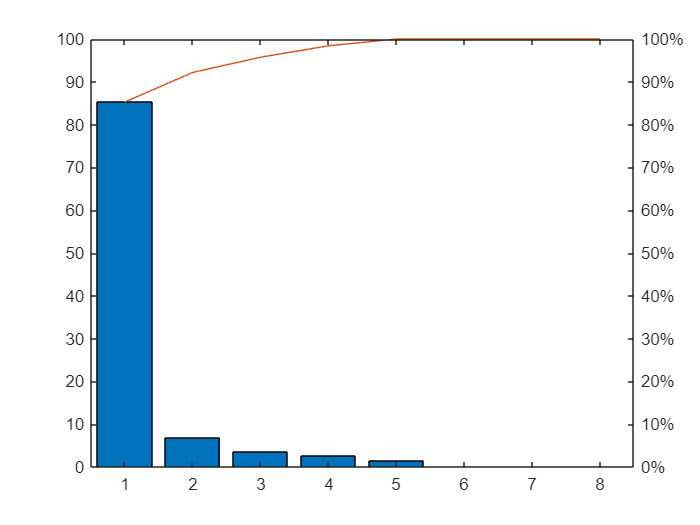

close all;
figure;
pareto(explained,1)

## Examine the principle component variances

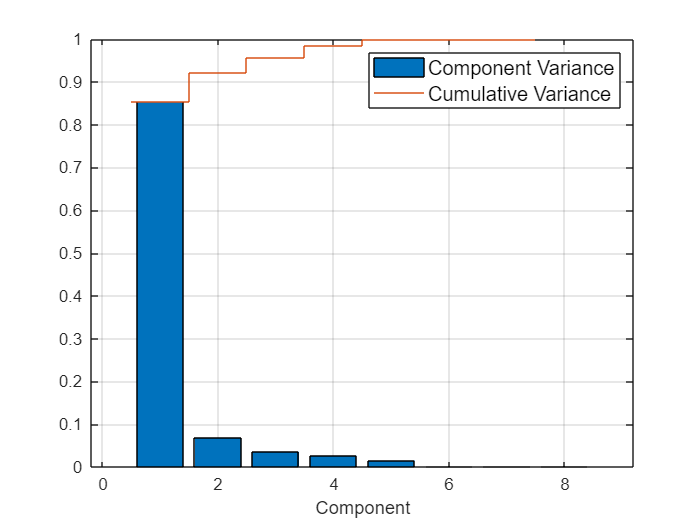

Vnorm = V/sum(V); % Normalize the variance so the total is 1
figure; hold on;
bar(Vnorm);
stairs(0.5:7.5,cumsum(Vnorm));
grid on; box on; hold off;
set(gca,'XTick',0:2:8)
legend({'Component Variance','Cumulative Variance'},'FontSize',12)
xlabel('Component')

## Examine the original feature variances

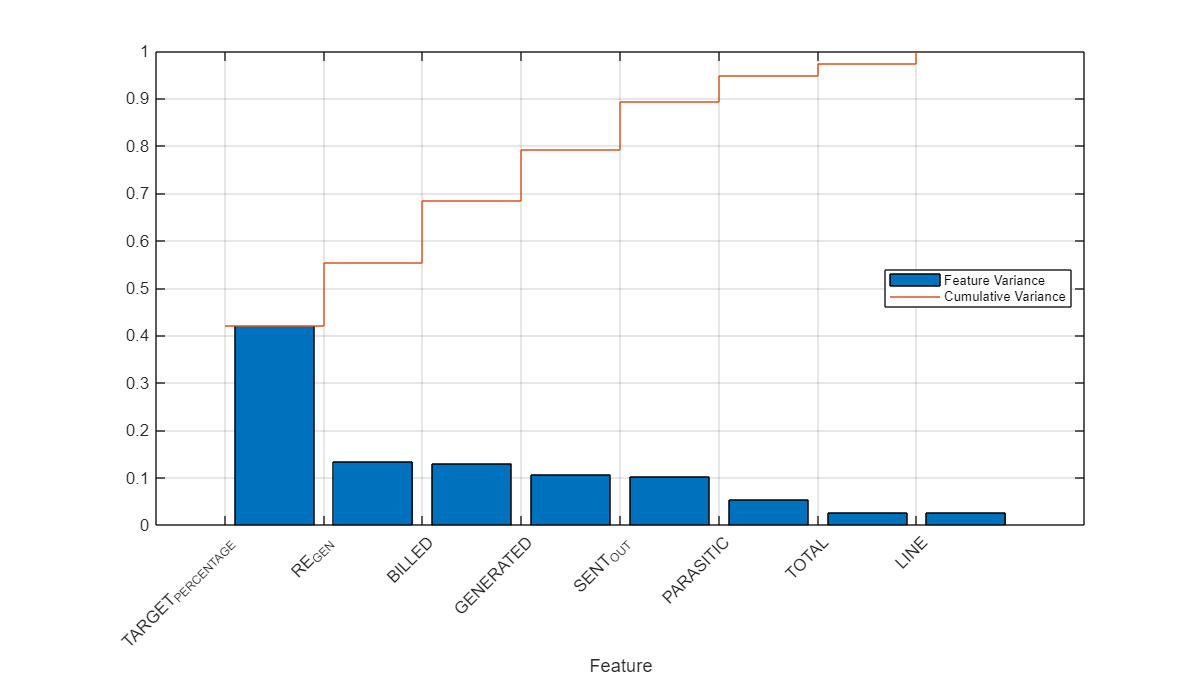

VOrigNorm = var(X);
[VOrigNorm,idx] = sort(VOrigNorm,'descend');
VOrigNorm = VOrigNorm/sum(VOrigNorm); % Normalize the variance so the total is 1
figure; hold on;
bar(VOrigNorm);
stairs(0.5:7.5,cumsum(VOrigNorm));
grid on; box on; hold off;
set(gca,'XTick',0.5:7.5,'XTickLabel',tbl.Properties.VariableNames(idx),'XTickLabelRotation',45)
set(gcf,'units','normalized','OuterPosition',[0 0 1 1])
legend({'Feature Variance','Cumulative Variance'},'FontSize',8,'Location','east')
xlabel('Feature')
ylim([0,1])

## Relating the principle components to the original variables

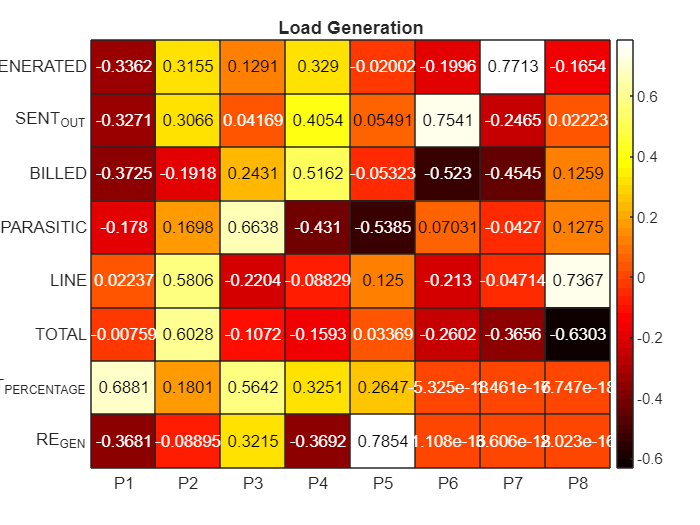

figure;
heatmap(P,'XDisplayLabels',"P"+(1:8),'YDisplayLabels',tbl.Properties.VariableNames,'Title','Load Generation','Colormap',hot(50));
set(gcf,'units','normalized','outerposition',[0 0 1 1])

## Visualizing the components features

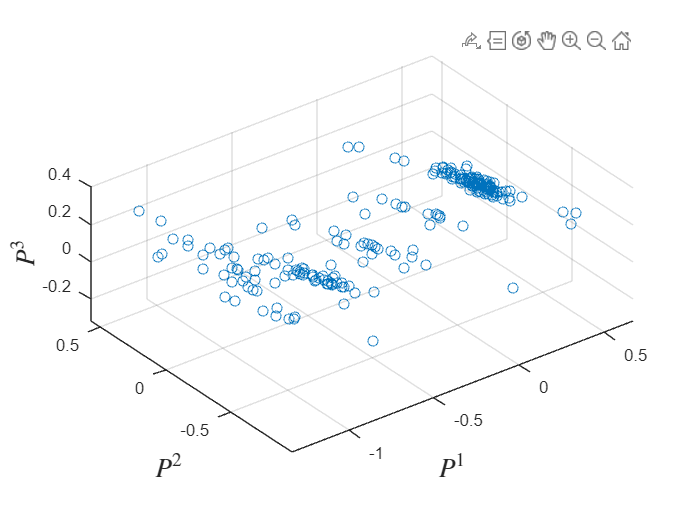

figure;
scatter3(S(:,1),S(:,2),S(:,3))
xlabel('$P^1$','FontSize',16,'Interpreter','latex')
ylabel('$P^2$','FontSize',16,'Interpreter','latex')
zlabel('$P^3$','FontSize',16,'Interpreter','latex')
axis equal;

## Clustering the component features

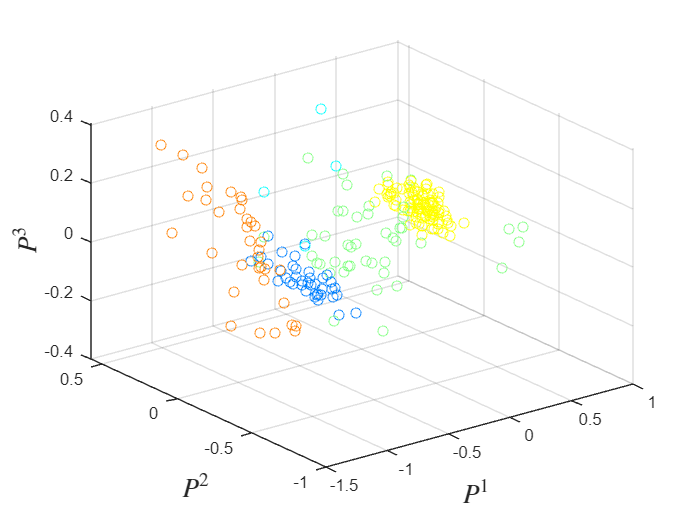

k = 5; % Number of clusters
components = 3; % Number of components features to use in clustering
opts = statset('MaxIter',500); 
gmm = fitgmdist(S(:,1:components),k,'Options',opts,'Replicates',10,'Start','randSample');
clst = cluster(gmm,S(:,1:components));
clr = jet(k);
figure; 
scatter3(S(:,1),S(:,2),S(:,3),[],clr(clst,:))
xlabel('$P^1$','FontSize',16,'Interpreter','latex')
ylabel('$P^2$','FontSize',16,'Interpreter','latex')
zlabel('$P^3$','FontSize',16,'Interpreter','latex')

## Using clusters to explore the original features%%%

tbl.Cluster = clst;

Unrecognized function or variable 'clst'.


feat = "GENERATED";
groupsummary(tbl,'Cluster',{'mean','median','max','min','range','std','var'},feat)

figure; hold on;
for i = 1:k
    histogram(tbl.(feat)(tbl.Cluster == i),50,'BinLimits',[min(tbl.(feat)),max(tbl.(feat))],'FaceAlpha',0.3)
end
legend("Cluster " + (1:6))
title(feat + " values by cluster")
hold off;

stat = "min";
data = groupsummary(X,clst,stat);
heatmap(tbl.Properties.VariableNames(1:end-1),"Cluster "+(1:8),data);

## Converting features to scores

S = X*P;

Xnew = (Xnew-mu)./r;
Snew = Xnew*P(:,1:components);

## Converting scores to features

X = S*P';
X = X.*r+mu;

Sclst = gmm.mu; % 6 (cluster) x 7 (component) centroid locations
Xclst = Sclst*P(:,1:components)'; % Convert to original feature coordinates
Xclst = Xclst.*r+mu; % Undo scaling and mean centering
tblClst = array2table([(1:6)',Xclst],'VariableNames',['Cluster',tbl.Properties.VariableNames(1:end-1)])